# Experimento 1 - Filtros Adaptativos

**PSI3531 Processamento de Sinais Aplicado**

Bruno Hashimoto 

Guilherme Fernandes Gonçalves Silva (10297272)

## Eliminação de Interferências

Declaração de variáveis

M = 2; % coeficientes do filtro adaptativo
N = 1000; % numero de pontos
n = 0:N-1;
phi_v = 2*pi*rand;% (2*pi)*rand(N,1); % U ~ [0, 2pi]
phi_u = phi_v;

s = sqrt(0.01) .* randn(N, 1); % s(n) - ruido branco (0, 0.01)
x = sin(2*pi*n/10 + pi/6 + phi_v')' ; % x(n) - interferencia
u = 5*sin(2*pi*n/10 + phi_u')'; % u(n) - sinal correlacionado com interferencia

d = s + x; % d(n) - 

a) 

Calcule a Matrix de autocorrelação R e o vetor de correlação cruzada p entre a entrada e o sinal desejado.

% Autocorrelation Matrix (R) calculation
r = xcorr(u, M-1, 'biased');
ru = r(M:end);
R = toeplitz(ru)

R =    12.5000   10.0910
   10.0910   12.5000



% cross-correlation (p) vector calculation
rdu = xcorr(d, u, M-1, 'biased');
p = rdu(M:end)

p =     2.1579
    1.0087


Calcule o vetor de coeficientes ótimos w_o

% optimal coeficients vector (w0)
w0 = R \ p % inv(R) * p

w0 =     0.3086
   -0.1684


Erro quadrático médio mínimo J_min

J_min = var(d) - p'*w0

J_min = 0.0118

Resposta em frequência

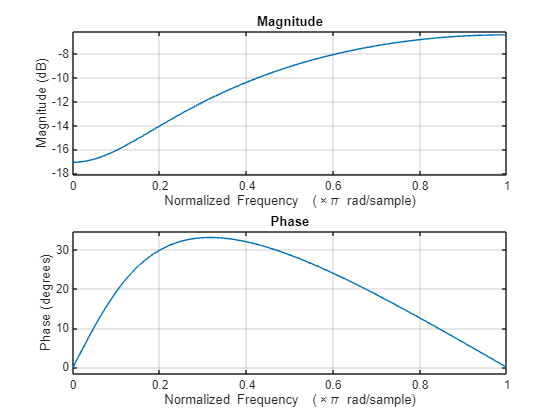

freqz(w0, 1);

b)

eigenvalues = eig(R);
fprintf('0 < mu < %f', 2/max(eigenvalues));

0 < mu < 0.088531

c)

Define variables

N_iter = 500;
mu = 0.03;
sigma_d_2 = 0.51;

sa

% i
[W, erro] = lms(u, d, M, N_iter, mu);
% plotar u e s com indice do numero de iteracoes (?)
plot(0:N_iter-1, u, 0:N_iter, erro, n, s);
legend('u(n)', 'e(n)', 's(n)');
xlim([0, 50]);
title('TODO: need a title');
xlabel('Number of iterations');
ylabel('Signals');

%% ii
plot(0:N, W, 0:N, ones(501,2).*w_0');
title('Coeficientes');
legend('Ótimo: 0,3108 ', 'Ótimo: -0,1701', 'Adap. Ref: 0,3108', 'Adap. Ref: -0,1701');
xlabel('Number of iterations');
ylabel('Signals');
% add horizontal line here
% https://www.mathworks.com/help/matlab/ref/yline.html

%% iii
W1 = -1:0.01:1;
Wnc = [W1;W1];

J = sigma_d_2 - 2*Wnc'*p + Wnc'*R*Wnc;

contour(W1, W1, J);
hold on;
plot(W(:,2), W(:,1));
title('NAME ME');
xlabel('X LABEL FIXME');
ylabel('X LABEL FIXME');

a

%% iv
N_iter2 = 1000;
erro_med = zeros(1,N_iter);

for i = 0:N_iter2-1
    phi_u = 2*pi*rand;
    x = sin(2*pi*n/10 + pi/6 + phi_u);
    u = 5*sin(2*pi*n/10 + phi_u);
    s = sqrt(0.01)*randn(1,N);
    d = s + x;

    [W, erro] = lms(u, d, M, N, mu);
    erro_med = erro_med + erro.*erro;
end
erro_med = erro_med/r;

db = 10*log10(erro_med);


plot(1:N, db);
ylim([-20 0]);
ylabel();
xlabel();
title();


d)

% d)
mu = 0.065; % entre 0.065 e 0.07
it = 1000;
W_med = zeros(501,2);
for i = 1:it;
    phi_u = 2*pi*rand;
    u = 5*sin(2*pi*n/10 + phi_u);
    s = sqrt(0.01)*randn(1,N);
    x = sin(2*pi*n/10 + pi/6 + phi_u);
    d = s + x;
    [W, erro] = lms(u, d, M, N, mu);
    W_med = W_med + W;
end;
W_med = W_med/it;
figure(5);
plot(0:N, W_med, 0:N, ones(501,2).*w_0');

e)

%% i
r = 1000;
mu = 0.03;
erro_med = zeros(1,500);
mse=[];
for i = 1:r
    phi_u = 2*pi*rand;
    x = sin(2*pi*n/10 + pi/6 + phi_u);
    u = 5*sin(2*pi*n/10 + phi_u);
    s = sqrt(0.01)*randn(1,N);
    d = s + x;
    [W, erro] = lms(u, d, M, N, mu);
    erro_med = erro_med + erro.*erro;
end
mse=erro_med/r;

plot(1:N, mse);

%% ii
sigma_v_2 = 0.01 %var(x);
%experimental
EMSEe = mse - J_min;
%teorico
EMSE = mu*sigma_v_2*trace(R)/(2-mu*trace(R))

plot(1:N, mse, 1:N, EMSEe, 1:N, ones(500,1).*J_min);
legend('mse', 'EMSE', 'J_min');
ylim([0 0.1]);